# Laplace Transform Lab: Solving ODEs using Laplace Transform in MATLAB

This lab will teach you to solve ODEs using a built in MATLAB Laplace transform function `laplace`.

There are five (5) exercises in this lab that are to be handed in. Write your solutions in a separate file, including appropriate descriptions in each step.

Include your name and student number in the submitted file.

## Student Information

## Using symbolic variables to define functions

In this exercise we will use symbolic variables and functions.

%syms t s x y

%f = cos(t)
%h = exp(2*x)

## Laplace transform and its inverse

% The routine |laplace| computes the Laplace transform of a function

%F=laplace(f)

By default it uses the variable `s` for the Laplace transform But we can specify which variable we want:

%H=laplace(h)
%laplace(h,y)

% Observe that the results are identical: one in the variable |s| and the
% other in the variable |y|

We can also specify which variable to use to compute the Laplace transform:

%j = exp(x*t)
%laplace(j)
%laplace(j,x,s)

% By default, MATLAB assumes that the Laplace transform is to be computed
% using the variable |t|, unless we specify that we should use the variable
% |x|

We can also use inline functions with `laplace`. When using inline functions, we always have to specify the variable of the function.

%l = @(t) t^2+t+1
%laplace(l(t))

MATLAB also has the routine `ilaplace` to compute the inverse Laplace transform

%ilaplace(F)
%ilaplace(H)
%ilaplace(laplace(f))

If `laplace` cannot compute the Laplace transform, it returns an unevaluated call.

%g = 1/sqrt(t^2+1)
%G = laplace(g)

But MATLAB "knows" that it is supposed to be a Laplace transform of a function. So if we compute the inverse Laplace transform, we obtain the original function

%ilaplace(G)

The Laplace transform of a function is related to the Laplace transform of its derivative:

%syms g(t)
%laplace(diff(g,t),t,s)

## Exercise 1

Objective: Compute the Laplace transform and use it to show that MATLAB 'knows' some of its properties.

Details: 

(a) Define the function `f(t)=exp(2t)*t^3`, and compute its Laplace transform `F(s)`. (b) Find a function `f(t)` such that its Laplace transform is  `(s - 1)*(s - 2))/(s*(s + 2)*(s - 3)` (c) Show that MATLAB 'knows' that if `F(s)` is the Laplace transform of  `f(t)`, then the Laplace transform of `exp(at)f(t)` is `F(s-a)` 

(in your answer, explain part (c) using comments). 

% a:
syms t s x; % t for f9t), s for F(s), 
f = exp(2*t)*t^3;
F = laplace(f);
display(F); % which is F(s)

$$F = \frac{6}{{\left(s-2\right)}^{4}}$$

% b: 
g =  ((s - 1)*(s - 2))/(s*(s + 2)*(s - 3));
G = ilaplace(g);
display(G);

$$G = \frac{6\,{\mathrm{e}}^{-2\,t}}{5}+\frac{2\,{\mathrm{e}}^{3\,t}}{15}-\frac{1}{3}$$

% in this case G is f(t)
% c: 
syms f(t) a g(t) t;
g(t) = exp(a*t)*f(t); 

hi = laplace(f(t));
hi_2 = laplace(g(t));
display(hi);

$$hi = \mathrm{laplace}\left(f\left(t\right),t,s\right)$$

display(hi_2);

$$hi\_2 = \mathrm{laplace}\left(f\left(t\right),t,s-a\right)$$

% this demonstrates that Matlab knows that if F(s) is the Laplace transform
% of f(t), then the Laplace transform of exp(at)f(t) is F(s-a) 
% This is shown in part C that I have laplace(f(t),t,s) for hi which is
% laplace of f(t)), and hi_2 for laplace(f(t),t,s-a) which is laplace of
% exp(a*t)*f(t).
% laplace(f(t), t, s) and laplace(f(t), t, s - a) are output for hi and
% hi_2 respectively. 
% This demonstrates that whenever f(t) is muliplied by exp(a*t) (which is
% g(t) in this case, this will shift by -a, as you can see from the output.
% this is property of laplace, therefore, MAT knows it. 
% 
% output: 
% hi = laplace(f(t), t, s)
% laplace(f(t), t, s - a)




Observe that MATLAB splits the rational function automatically when solving the inverse Laplace transform.

## Heaviside and Dirac functions

These two functions are builtin to MATLAB: `heaviside` is the Heaviside function `u_0(t)` at `0`

To define `u_2(t)`, we need to write

%f=heaviside(t-2)
%ezplot(f,[-1,5])

% The Dirac delta function (at |0|) is also defined with the routine |dirac|

%g = dirac(t-3)

% MATLAB "knows" how to compute the Laplace transform of these functions

%laplace(f)
%laplace(g)

## Exercise 2

Objective: Find a formula comparing the Laplace transform of a translation of `f(t)` by `t-a` with the Laplace transform of `f(t)`

Details: 

- Give a value to `a`

- Let `G(s)` be the Laplace transform of `g(t)=u_a(t)f(t-a)` and `F(s)` is the Laplace transform of `f(t)`, then find a formula relating `G(s)` and `F(s)`

close all; clear; clc;
syms a s t;
% give a vlue to a which is 2 arbitary. 
% a = 1;
% a = 2;
% a = 3;
% a = 4;
% a = 5; 
a = 5; 
% define heavisidefunction 
u_a(t) = heaviside(t-a);
%let
f= @(t) exp(2*t)*t^3; %(from exercise 1)

% Now define g(t)

g(t) = u_a(t) * f(t-a);
G(s) = laplace(g, t, s);

% laplace of f
F = laplace(f(t), t, s);
% now time to display@!
display(F);

$$F = \frac{6}{{\left(s-2\right)}^{4}}$$

display(G);

$$G(s) = \frac{6\,{\mathrm{e}}^{-5\,s}}{{\left(s-2\right)}^{4}}$$


% F = 6/(s - 2)^4 and G(s) = (6*exp((-5*s)))/(s - 2)^4.
% Whenever chaniging the "a" value manually, this changes the
% (6*exp((-a*s)))/(s - 2)^4. a in output of G(s). 

% Equation: G(s) = F(s)*exp(-a*s)


% in exercise 1, we saw that "% This demonstrates that whenever f(t) is muliplied by exp(a*t) (which is
% g(t) in this case, this will shift by -a, as you can see from the output.
% this is property of laplace."

% in exercise 2, this is done other way around. this time we multiply step
% function with f(t-a) which is shifted by a, then we get the value that
% mulipiled by exp(a*t).

% As in exerices 1 and exercise 2 is proved in both other ways,
% therefore, the equation is proved % Equation: G(s) = F(s)*exp(-a*s). 




In your answer, explain the 'proof' using comments.

## Solving IVPs using Laplace transforms

Consider the following IVP, `y''-3y = 5t` with the initial conditions `y(0)=1` and `y'(0)=2`. We can use MATLAB to solve this problem using Laplace transforms:

% First we define the unknown function and its variable and the Laplace
% tranform of the unknown

%syms y(t) t Y s;

% Then we define the ODE

%ODE=diff(y(t),t,2)-3*y(t)-5*t == 0;

% Now we compute the Laplace transform of the ODE.

%L_ODE = laplace(ODE);

% Use the initial conditions

%L_ODE=subs(L_ODE,y(0),1);
%L_ODE=subs(L_ODE,subs(diff(y(t), t), t, 0),2);

% We then need to factor out the Laplace transform of |y(t)|

%L_ODE = subs(L_ODE,laplace(y(t), t, s), Y);
%Y=solve(L_ODE,Y);

% We now need to use the inverse Laplace transform to obtain the solution
% to the original IVP

%y = ilaplace(Y);

% We can plot the solution

%ezplot(y,[0,20]);

% We can check that this is indeed the solution

%diff(y,t,2)-3*y;

## Exercise 3

Objective: Solve an IVP using the Laplace transform

Details: Explain your steps using comments

- Solve the IVP

- `y'''+2y''+y'+2*y=-cos(t)`

- `y(0)=0`, `y'(0)=0`, and `y''(0)=0`

- for `t` in `[0,10*pi]`

- Is there an initial condition for which `y` remains bounded as `t` goes to infinity? If so, find it.

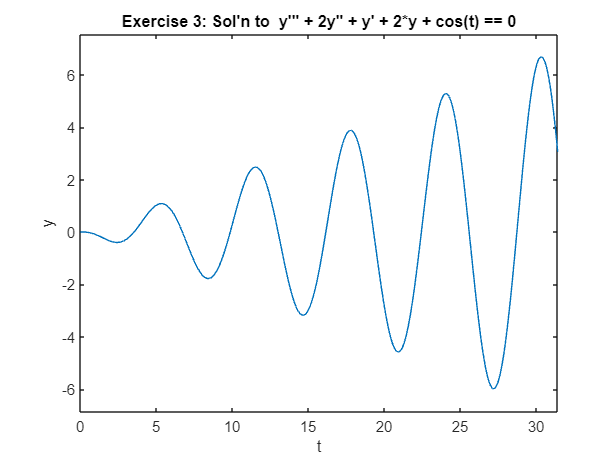

% First we define the unknown function and its variable and the Laplace
% tranform of the unknown
% y''-3y = 5t with the initial conditions y(0)=1 and y'(0)=2

syms y(t) t Y s;

% in this problem: y''' + 2y'' + y' + 2*y + cos(t) == 0
% initial condition y(0) = 0, y'(0) = 0. y''(0) = 0

% Then we define the ODE
% ODE = diff(y(t),t,2)-3*y(t)-5*t == 0
ODE = diff(y(t), t, 3) +2*diff(y(t), t, 2) + diff(y(t), 1) +2*y(t) + cos(t) == 0;
% Now we compute the Laplace transform of the ODE.

L_ODE = laplace(ODE);

% Use the initial conditions
L_ODE=subs(L_ODE,y(0),0); % for y(0) = 0
L_ODE=subs(L_ODE,subs(diff(y(t), t), t, 0),0); % for y'(0) = 0
L_ODE=subs(L_ODE,subs(diff(y(t), t, t), t, 0),0); % for y''(0) = 0

% We then need to factor out the Laplace transform of |y(t)|
L_ODE = subs(L_ODE,laplace(y(t), t, s), Y);
Y=solve(L_ODE,Y);

% We now need to use the inverse Laplace transform to obtain the solution
% to the original IVP

y = ilaplace(Y);

% We can plot the solution
ezplot(y,[0,10*pi]);

title("Exercise 3: Sol'n to  y''' + 2y'' + y' + 2*y + cos(t) == 0");
xlabel("t");
ylabel("y");


% Is there an initial condition for which y remains bounded as t goes to infinity? If so, find it.
% There is no initial condition that when t goes to infinity while y
% remains bounded. This can be seen from the plotted graph, as t goes
% infinity, y is osciliating and growing. Therefore, there is no initial
% condition for y reamins bounded as t -> inf. When the function is
% oscillating and growing, this won't bound ever. 

## Exercise 4

Objective: Solve an IVP using the Laplace transform

Details: 

- Define 

- `g(t) = 3 if 0 < t < 2`

- `g(t) = t+1 if 2 < t < 5`

- `g(t) = 5 if t > 5`

- Solve the IVP

- `y''+2y'+5y=g(t)`

- `y(0)=2 and y'(0)=1`

- Plot the solution for `t` in `[0,12]` and `y` in `[0,2.25]`.

In your answer, explain your steps using comments.

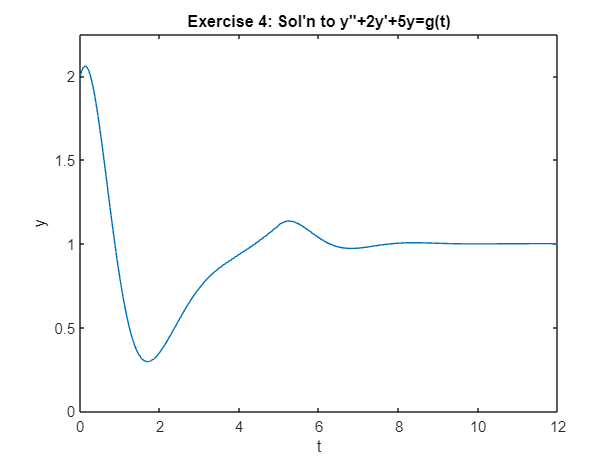

% assume "explain your steps using comments" means add comments in the
% code to explain each step"

syms y(t) t Y s;

hi_0(t) = heaviside(t);
hi_1(t) = heaviside(t-2);
hi_2(t) = heaviside(t-5); % These are based on the range for the heaviside functions for making one huge g(t)

% now define the func based on the range and heaviside function
g(t) = 3*hi_0(t) + (t-2)*hi_1(t) + (-t+4)*hi_2(t);

% ODE is defined as last time. 
ODE = diff(y(t), t, 2) + 2*diff(y(t), 1) +5*y(t) - g(t)== 0;

% Now we compute the Laplace transform of the ODE.
L_ODE = laplace(ODE);

% Use the initial conditions
L_ODE=subs(L_ODE,y(0),2); % for y(0) = 2
L_ODE=subs(L_ODE,subs(diff(y(t), t), t, 0),1); % for y'(0) = 1
% We then need to factor out the Laplace transform of |y(t)|

L_ODE = subs(L_ODE,laplace(y(t), t, s), Y);
Y=solve(L_ODE,Y);

% We now need to use the inverse Laplace transform to obtain the solution
% to the original IVP

y = ilaplace(Y);

% We can plot the solution

ezplot(y,[0,12,0,2.25]);

title("Exercise 4: Sol'n to y''+2y'+5y=g(t)");
xlabel("t");
ylabel("y");


simplify(diff(y,t,2)+2*diff(y,t)+5*y-g)

$$ans(t) = 3-3\,\mathrm{heaviside}\left(t\right)$$

% This gives me 3 - 3*heaviside(t) which is equal to 0 when heaviside(t) =
% 1. (This is step function). 
% This demonstrates my sovling is correct. 

## Exercise 5

Objective: Use the Laplace transform to solve an integral equation

Verify that MATLAB knowns about the convolution theorem by explaining why the following transform is computed correctly.

syms t tau y(tau) s
I=int(exp(-2*(t-tau))*y(tau),tau,0,t)

$$I = \int_{0}^{t}{\mathrm{e}}^{2\,\tau -2\,t}\,y\left(\tau \right)\mathrm{d}\tau$$

laplace(I,t,s)

$$ans = \frac{\mathrm{laplace}\left(y\left(t\right),t,s\right)}{s+2}$$


% That inetgral can be denoted as convolution intgeral 
% which can be changed to (f*g)(t) = int(exp((2*tau - 2*t))*y(tau), tau, 0,
% t) where f is equal to exp((2*tau - 2*t)) and g is equal to y. 
% Now, we can do the lapalce convolution to see if the answer is right. 
% Laplace convolution theorem shows that lapace{f(t) *g(t)} = F(s)G(s) 
% where F(s) = laplace{f(t)} and G(s) = laplace{g(t)}.
%  We know that f which is exp(2t) will be 1/(s+2) under laplace transform. Threfore,
%  this is shown the answer should be product of 1/(s+2) and laplace(y(t))
%  which is g. Now, this is shown that the answer is correct. 
